# **ECG CLASSIFICATION USING LINEAR REGRESSION**

The aim of this project is to classify heartbeats as **Normal** or **Abnormal** using machine learning. The model is trained on the **MIT-BIH Arrhythmia Dataset**, which contains ECG (Electrocardiogram) data with 187 features per sample. This binary classification system maps multi-class heartbeat annotations to two categories:

- **Normal (0)**: Regular heart activity.

- **Abnormal (1)**: Irregular heart activity, indicating potential arrhythmias.

% Function to classify heartbeats as Normal or Abnormal using Linear Regression
function classify_heartbeat_linear(uploaded_file, trained_model, min_vals, max_vals)
    % Check if file exists
    if ~isfile(uploaded_file)
        error('File does not exist. Please provide a valid file path.');
    end
    
    % Load the new dataset
    fprintf('Loading data from %s...\n', uploaded_file);
    new_data = readtable(uploaded_file);

    % Separate features and labels 
    features = new_data(:, 1:end-1); 
    % Exclude the last column
    num_features = width(features);
    
    % Normalize the features using training set min and max
    fprintf('Normalizing features...\n');
    features_normalized = normalize_features(features, min_vals, max_vals);

    % Predict using the trained model
    fprintf('Classifying heartbeats...\n');
    continuous_predictions = predict(trained_model, features_normalized);
    % Threshold for binary classification
    predictions = continuous_predictions > 0.5;

    % Display results
    fprintf('Classification Results:\n');
    for i = 1:length(predictions)
        fprintf('Sample %d: %s\n', i, classify_label(predictions(i)));
    end
end

% function to Normalize features column-wise using training set min/max
function normalized_features = normalize_features(features, min_vals, max_vals)
    features_array = features{:,:};
    normalized_features = (features_array - min_vals) ./ (max_vals - min_vals);
end

%Function to Convert binary label to "Normal" or "Abnormal"
function label = classify_label(binary_label)
    if binary_label == 0
        label = 'Normal';
    else
        label = 'Abnormal';
    end
end


## Train the model and classify new data


% Load the training dataset
training_file = 'C:\Users\sathy\MIT train\mitbih_train.csv';
fprintf('Loading training data from %s...\n', training_file);

data = readtable(training_file);

% Separate features and labels

Loading training data from C:\Users\sathy\MIT train\mitbih_train.csv...


features = data(:, 1:end-1);
labels = data{:, end}; % Last column as labels

% Map labels: 
% 0 - Normal 
% 1+ - Abnormal
binary_labels = labels;
binary_labels(labels > 0) = 1;

% Normalize features
min_vals = min(features{:,:}, [], 1);
max_vals = max(features{:,:}, [], 1);
normalized_features = normalize_features(features, min_vals, max_vals);

% Split data into training and testing sets
num_samples = size(features, 1);
train_ratio = 0.8;
rng(42); % Set seed for reproducibility
index = randperm(num_samples);
train_idx = index(1:round(train_ratio * num_samples));
test_idx = index(round(train_ratio * num_samples) + 1:end);

X_train = normalized_features(train_idx, :);
y_train = binary_labels(train_idx);
X_test = normalized_features(test_idx, :);
y_test = binary_labels(test_idx);

% Train linear regression model
fprintf('Training linear regression model...\n');
model = fitlm(X_train, y_train);

% Evaluate on test data
y_pred = predict(model, X_test);

Training linear regression model...


predictions = y_pred > 0.5; % Threshold for binary classification

accuracy = mean(predictions == y_test) * 100;
fprintf('Model Accuracy on Test Data: %.2f%%\n', accuracy);

%converting y_test and prediction into the same type before making the confusionmat
% Convert logical to numeric
predictions = double(predictions);

Model Accuracy on Test Data: 90.34%


% Convert y_test to numeric
y_test = double(y_test);           


% Confusion Matrix
cm = confusionmat(y_test, predictions);
disp('Test Data Confusion Matrix:');
disp(cm);

fprintf('True Positives: %d\n', cm(2, 2));


Test Data Confusion Matrix:


fprintf('False Positives: %d\n', cm(1, 2));

       14185         235
        1456        1635




fprintf('False Negatives: %d\n', cm(2, 1));

True Positives: 1635



fprintf('True Negatives: %d\n', cm(1, 1));

False Positives: 235


False Negatives: 1456


% Plot ROC Curve
[X, Y, ~, AUC] = perfcurve(y_test, y_pred, 1)

True Negatives: 14185


plot(X, Y);
xlabel('False Positive Rate'); ylabel('True Positive Rate');
title(['ROC Curve (AUC = ' num2str(AUC) ')']);

##  Classify uploaded file

uploaded_file = 'C:\Users\sathy\MIT train\mitbih_test.CSV';

X =          0
         0
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


Y =          0
    0.0003
    0.0003
    0.0006
    0.0010
    0.0013
    0.0016
    0.0019
    0.0023
    0.0026


AUC = 0.8753

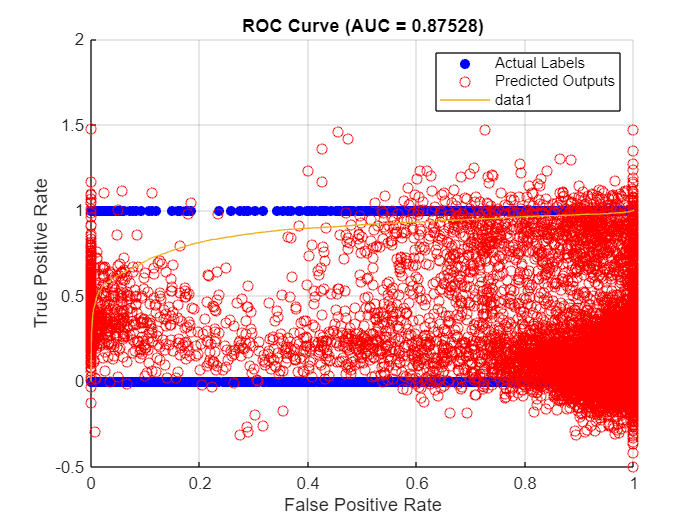

classify_heartbeat_linear(uploaded_file, model, min_vals, max_vals);



% Visualize the Linear Regression Model
feature_index = 1; % Select the feature index to visualize (e.g., the first feature)
fprintf('Visualizing feature %d against predictions...\n', feature_index);

Loading data from C:\Users\sathy\MIT train\mitbih_test.CSV...
Normalizing features...
Classifying heartbeats...
Classification Results:
Sample 1: Normal
Sample 2: Normal
Sample 3: Normal
Sample 4: Normal
Sample 5: Normal
Sample 6: Normal
Sample 7: Normal
Sample 8: Normal
Sample 9: Normal
Sample 10: Normal
Sample 11: Normal
Sample 12: Normal
Sample 13: Normal
Sample 14: Normal
Sample 15: Normal
Sample 16: Normal
Sample 17: Normal
Sample 18: Normal
Sample 19: Normal
Sample 20: Normal
Sample 21: Normal
Sample 22: Normal
Sample 23: Normal
Sample 24: Normal
Sample 25: Normal
Sample 26: Normal
Sample 27: Normal
Sample 28: Normal
Sample 29: Normal
Sample 30: Normal
Sample 31: Normal
Sample 32: Normal
Sample 33: Normal
Sample 34: Normal
Sample 35: Abnormal
Sample 36: Normal
Sample 37: Normal
Sample 38: Normal
Sample 39: Normal
Sample 40: Normal
Sample 41: Normal
Sample 42: Normal
Sample 43: Normal
Sample 44: Normal
Sample 45: Normal
Sample 46: Normal
Sample 47: Normal
Sample 48: Abnormal
Sampl


% Use the first feature for simplicity
X_single_feature = X_test(:, feature_index);

% Predict values for the test set

Visualizing feature 1 against predictions...


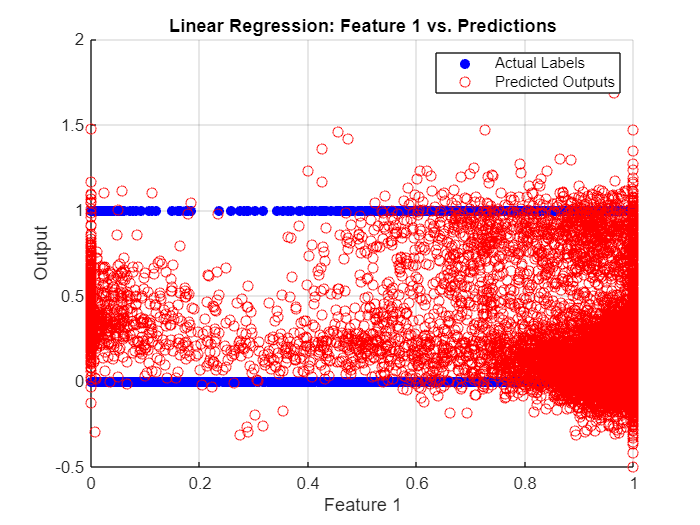

y_pred = predict(model, X_test);

% Scatter plot of feature vs. actual labels
figure;
scatter(X_single_feature, y_test, 'b', 'filled');
hold on;

% Line plot for feature vs. predicted labels
scatter(X_single_feature, y_pred, 'r');
xlabel(['Feature ', num2str(feature_index)]);
ylabel('Output');
legend('Actual Labels', 'Predicted Outputs');
title(['Linear Regression: Feature ', num2str(feature_index), ' vs. Predictions']);
grid on;


AIE_B_GROUP_9